# **demo of Im2mesh package**

**With the **`'opt.tf_preserve'`** option during 2d mesh generation**

Jiexian Ma, mjx0799@gmail.com. [Project website](https://github.com/mjx888/im2mesh).

## Setup

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size (optional).

x = 250; y = 250; width = 300; height = 300;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

Function bounds2mesh use a mesh generator called [MESH2D](https://github.com/dengwirda/mesh2d) (developed by Darren Engwirda). We can use the following command to add the folder 'mesh2d-master' to the path of MATLAB. 

addpath(genpath('mesh2d-master'))

## Single-part geometry

### A polyshape

Let's create a polyshape (for a single-part geometry). 

Suppose we want a square with a hole.

% square
vertex = 10*[ 0 0; 1 0; 1 1; 0 1 ];
psSq = polyshape(vertex);

Scale the unit square with respect to its centroid to create a tiny square, and rotate.

% scale
[x,y] = centroid(psSq);
refpoint = [x,y];
scale_factor = 0.15;
psSqTiny = scale(psSq, scale_factor, refpoint);

% rotate
[x,y] = centroid(psSqTiny);
refpoint = [x,y];
psSqTiny = rotate(psSqTiny, 45, refpoint);

Perform boolean operation to create a square with a hole.

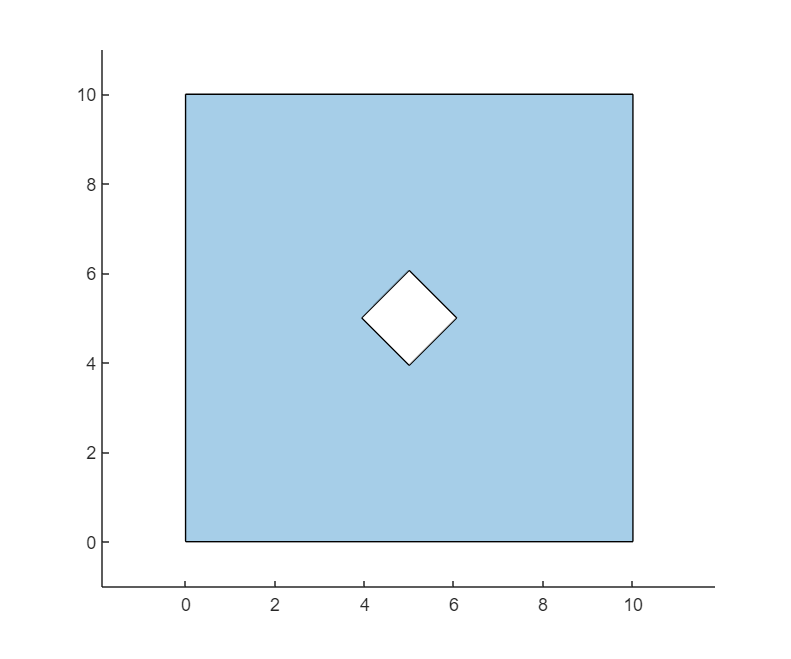

psSqHole = subtract(psSq, psSqTiny);

plot(psSqHole); 
axis equal

### Polygonal boundary

We use function polyshape2bound to convert a cell array of polyshape to a cell array of polygonal boundary. 

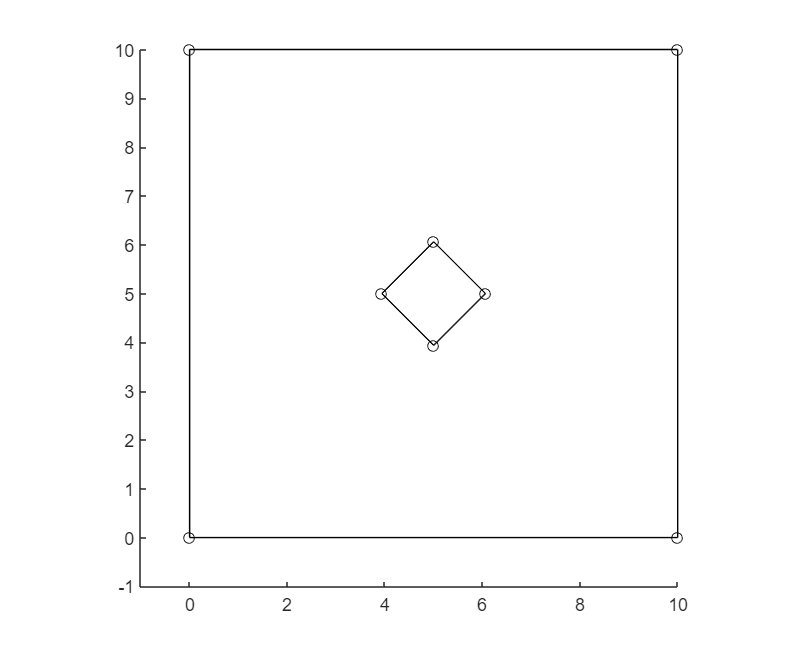

psCell = {psSqHole}; % psCell is a cell array of polyshape

bounds = polyshape2bound(psCell);

% plot boundaries and show all vertices
plotBounds(bounds,false,'ko-')

### Add mesh seeds to boundary

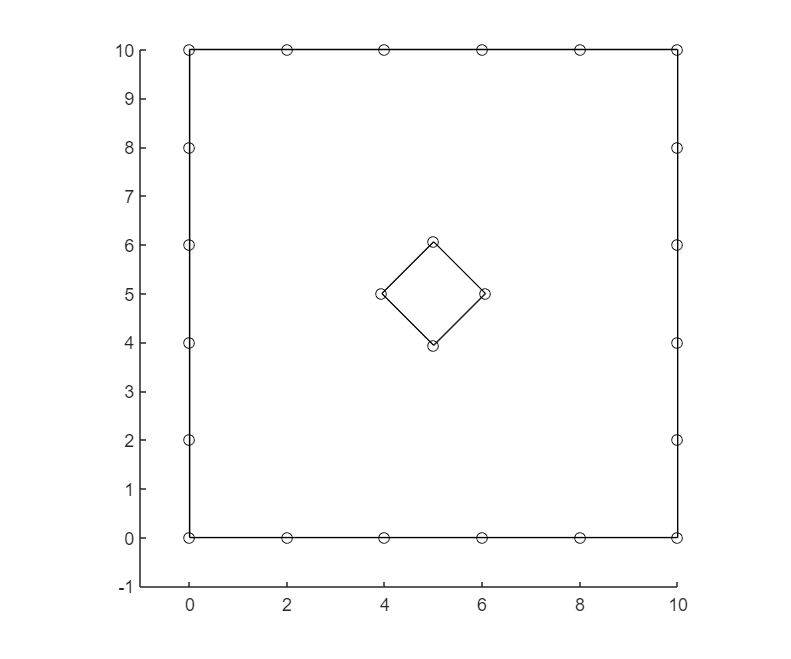

targetSpace = 2;
newB = refineOuterBoundary( bounds, targetSpace );

plotBounds(newB,false,'ko-')

### Generate mesh via MESH2D

To generate mesh, we use function bounds2mesh.

Note that function bounds2mesh uses [MESH2D](https://github.com/dengwirda/mesh2d) (developed by Darren Engwirda) as mesh generator.

hmax = 500; 
grad_limit = 0.25;
opt = [];
opt.disp = inf;     % silence verbosity
opt.tf_preserve = 1;

[vert,tria,tnum,vert2,tria2] = bounds2mesh( newB, hmax, grad_limit, opt );

Plot mesh.

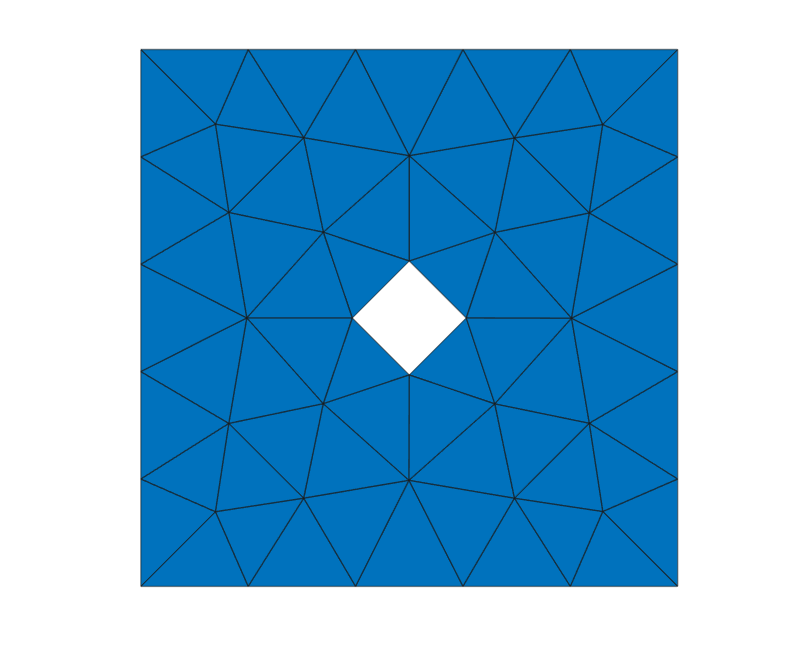

color = 1;
plotMeshes(vert,tria,tnum, color);

checkPBCNode( vert );

PBC Check Passed: All opposite boundary nodes are aligned.


We can use function tricost to check the mesh quality. 

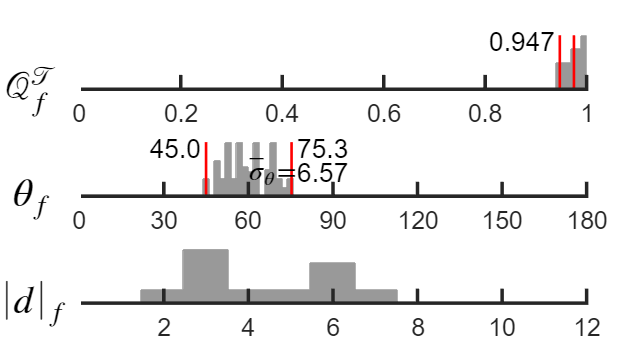

figure
tricost( vert, tria );

## Multi-part geometry

### Multiple polyshapes

Let's create multiple polyshapes for multi-part geometry.

clearvars

Start with a square.

vertex = 10*[ 0 0; 1 0; 1 1; 0 1 ];
psSq = polyshape(vertex);

Create a circle.

t = 0.05:0.1:2*pi;
x1 = 5 + 1.5*cos(t);
y1 = 5 + 1.5*sin(t);
psC0 = polyshape(x1,y1);

psC1 = translate( psC0, [5.1, 1.5] );
psC2 = translate( psC0, [-4.9, 1.5] );

psC3 = translate( psC0, [1, 5.6] );
psC4 = translate( psC0, [1, -4.4] );

Plot them together.

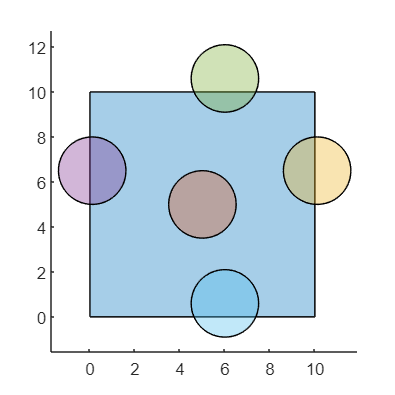

figure
plot( [psSq; psC0; psC1; psC2; psC3; psC4] ); 
axis equal

We saw that they are overlapped.

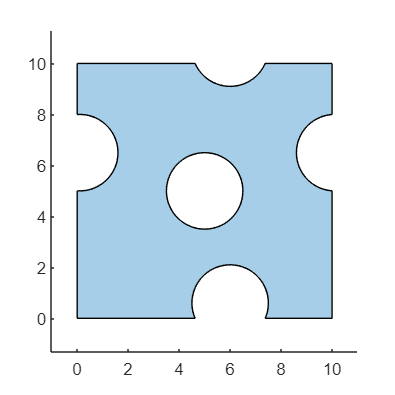

psMatrix = subtract( psSq, psC0 );

psMatrix = subtract( psMatrix, psC1 );
psMatrix = subtract( psMatrix, psC2 );

psMatrix = subtract( psMatrix, psC3 );
psMatrix = subtract( psMatrix, psC4 );

plot( psMatrix ); 
axis equal

psC1 = intersect( psC1, psSq );
psC2 = intersect( psC2, psSq );

psC3 = intersect( psC3, psSq );
psC4 = intersect( psC4, psSq );

Plot them together.

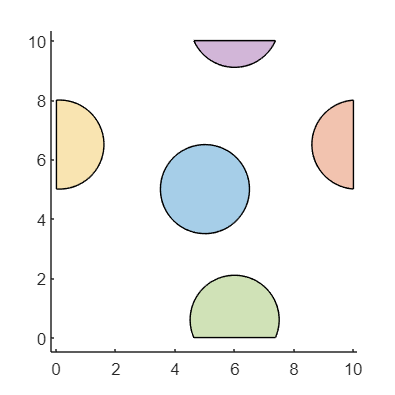

plot( [psC0; psC1; psC2; psC3; psC4] ); 
axis equal

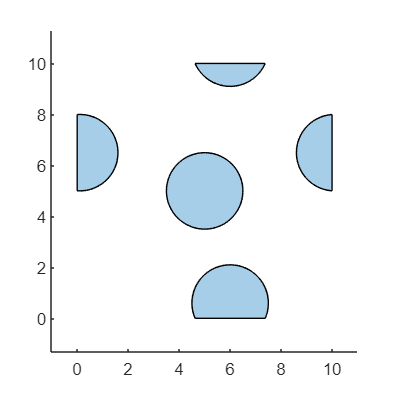

psFiber = psC0;
psFiber = union( psFiber, psC1);
psFiber = union( psFiber, psC2);
psFiber = union( psFiber, psC3);
psFiber = union( psFiber, psC4);

plot( psFiber ); 
axis equal

### Cell array of polyshape

We put them into a cell array - psCell. Each element in psCell represent different parts. It's like labelling.

psCell = { psMatrix; psFiber };

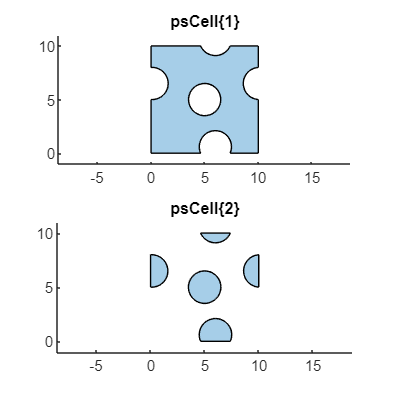

figure
for i = 1: length(psCell)
    subplot(2,1,i);
    plot( psCell{i} );  axis equal;
    title(['psCell\{' num2str(i), '\}']);
end

Convert the cell array of polyshape 'psCell' to a cell array of polygonal boundaries 'bounds'

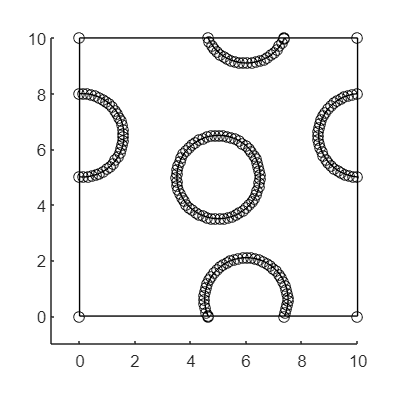

bounds = polyshape2bound(psCell);

% plot boundaries and show all vertices
plotBounds(bounds,false,'ko-')

### Add intersect points (optional)

Polyshape objects are not able to find intersect points automatically. Therefore, we use function addIntersectPnts to add intersect points to 'bounds'. 

Note that if we don't add intersect points, mesh generation **may** fail.

tol_intersect = 1e-6;   % distance tolerance for intersect
bounds = addIntersectPnts( bounds, tol_intersect );

### Simplify boundaries

We want to reduce the number of vertices on the circle.

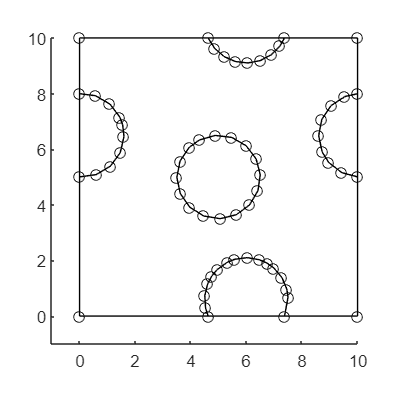

boundsCtrlP = getCtrlPnts( bounds );
tolerance = 0.04;  % for Douglas-Peucker polyline simplification
boundsReduced= simplifyBounds( boundsCtrlP, tolerance );

% show all vertices
plotBounds(boundsReduced,false,'ko-')

### Add mesh seeds to boundary

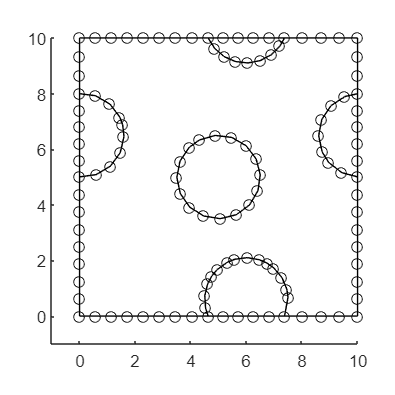

targetSpace = 0.6;
newB = refineOuterBoundary( boundsReduced, targetSpace );

plotBounds(newB,false,'ko-')

### Generate mesh via MESH2D

To generate mesh, we use function bounds2mesh.

Note that function bounds2mesh uses [MESH2D](https://github.com/dengwirda/mesh2d) (developed by Darren Engwirda) as mesh generator.

hmax = 500; 
grad_limit = 0.25;
opt = [];
opt.disp = inf;     % silence verbosity
opt.tf_preserve = 1;

[vert,tria,tnum,vert2,tria2] = bounds2mesh( newB, hmax, grad_limit, opt );

Plot mesh.

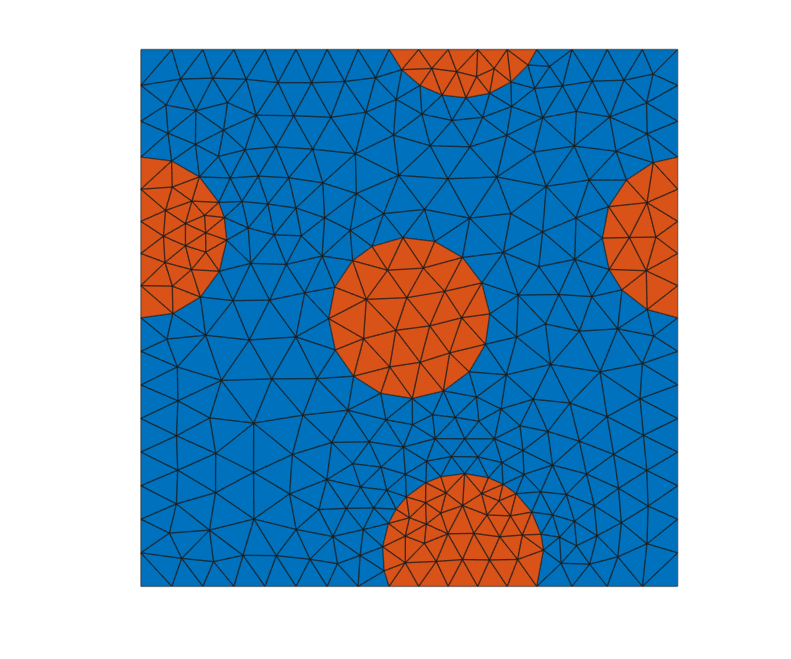

color = 1;
plotMeshes( vert,tria,tnum, color);

checkPBCNode( vert );

PBC Check Passed: All opposite boundary nodes are aligned.


We can use function tricost to check the mesh quality. 

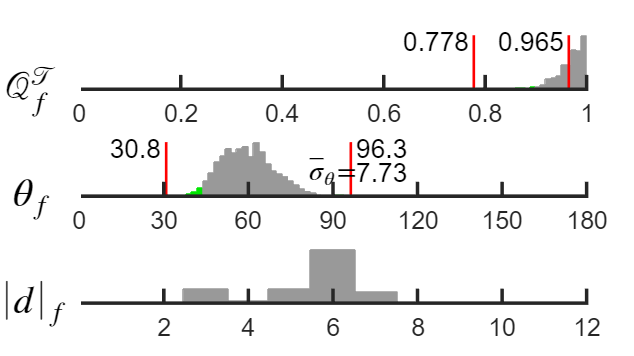

figure
tricost( vert, tria );

% psBlock = subtract( psSq, psCircle );
% 
% psBlock = subtract( psBlock, psC21 );
% psBlock = subtract( psBlock, psC22 );
% 
% psBlock = subtract( psBlock, psC31 );
% psBlock = subtract( psBlock, psC32 );
% 
% psBlock = subtract( psBlock, psC41 );
% psBlock = subtract( psBlock, psC42 );
% 
% plot( [psBlock; psCircle; psC21; psC22; psC31; psC32; psC41; psC42] ); 
% axis equal

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo